clear all; clc;
%生成白光干涉信号
%显示光谱信息
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
spectrum_intensity = (spectrum{:,2})';
disp("全部光谱信息");

全部光谱信息


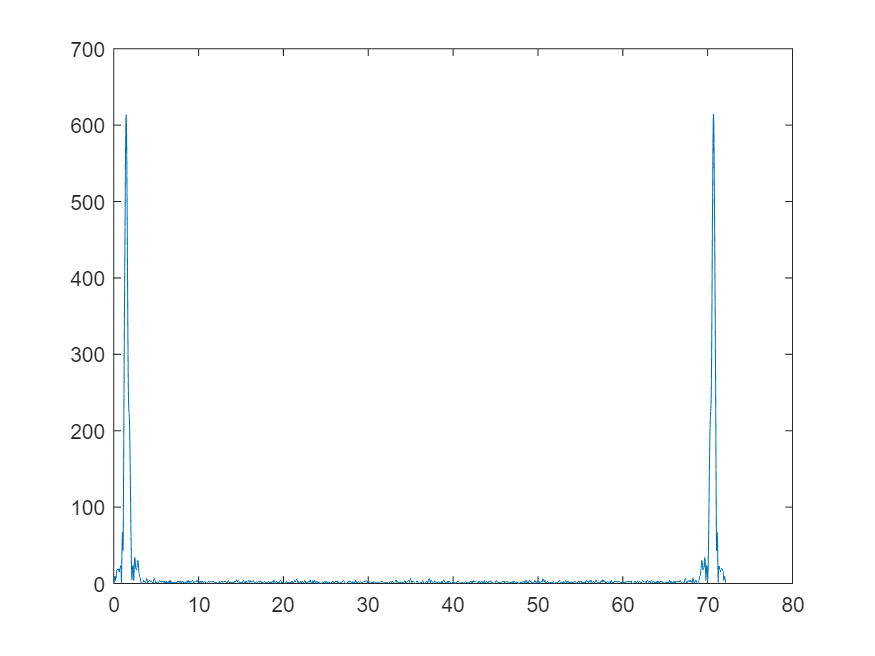

plot(spectrum_frequency,spectrum_intensity)

%找出探测器对应的光谱，这里假设是1.1-2.1
[Min, indix_min] = min(abs(spectrum_frequency-1.1));
[Max, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
disp("需要的光谱信息");

需要的光谱信息


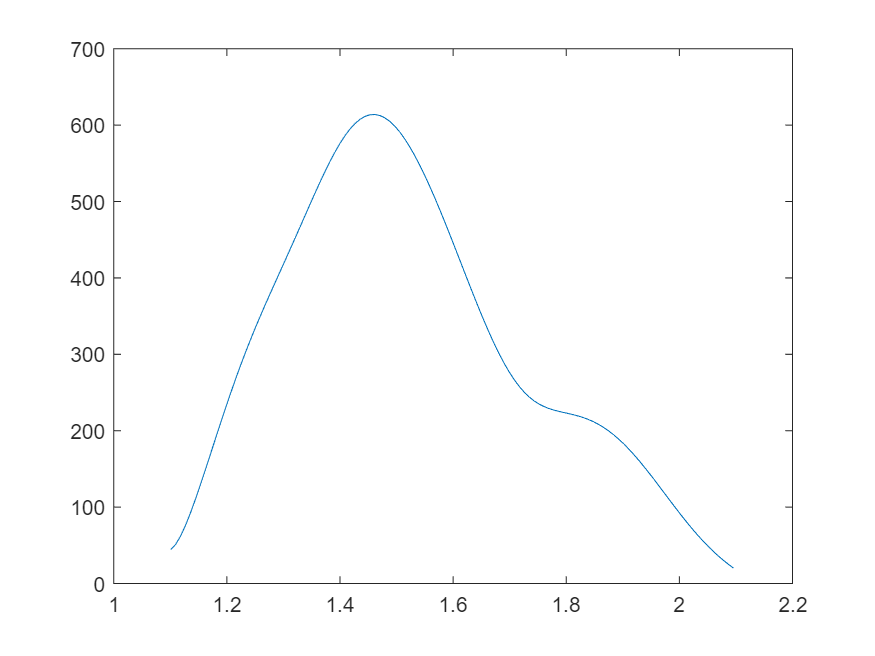

plot(spectrum_frequency,spectrum_intensity);

%生成白光干涉信号
z0 = 10;    %单位为微米
z = linspace(5,15,1024);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
    for n = 1:length(spectrum_frequency)
        interference_signal(i) = interference_signal(i)+2*spectrum_intensity(n)+...
        2*spectrum_intensity(n)*cos(4*pi*(z(i)-z0)*spectrum_frequency(n));
    end
end
disp("生成的白光干涉信号");

生成的白光干涉信号


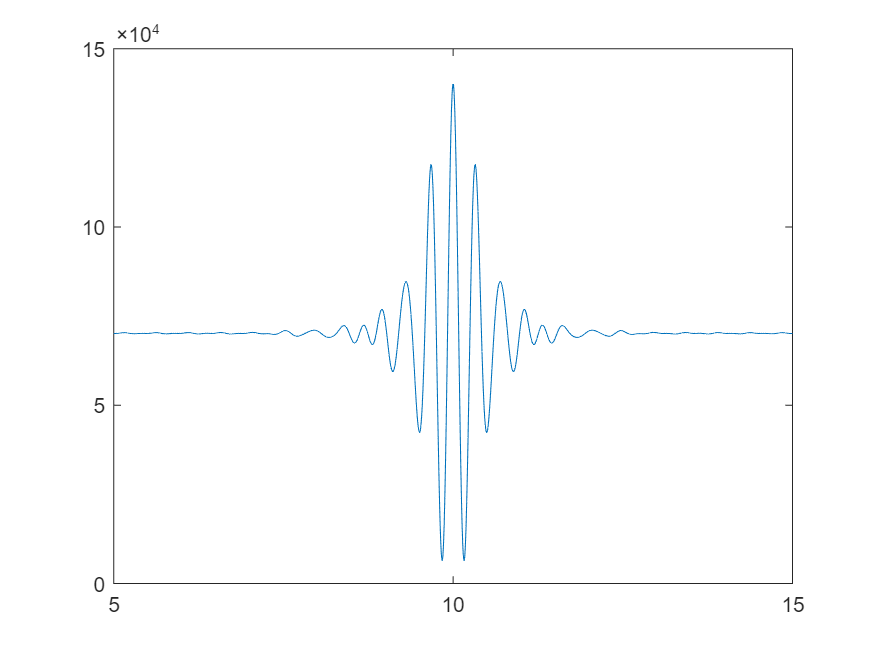

plot(z,interference_signal);